## Name:

## Date:

## PID: 

# Assignment 5 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Assignment files should be titled Assignment_X_FirstNameLastName, Ex: Assignment_5_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

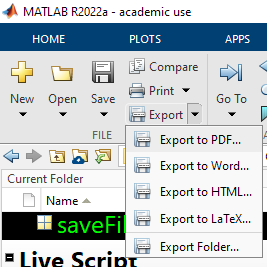

Question 1 (20%): 

A mutated strain of *Cordyceps* fungus has begun producing a strange bioluminescent sheen. Light striking the fungal layer diminishes quickly as spores absorb the energy for metabolic signaling. The amount of light absorbed depends on the material constant, μ, known as the absorption coefficient. 

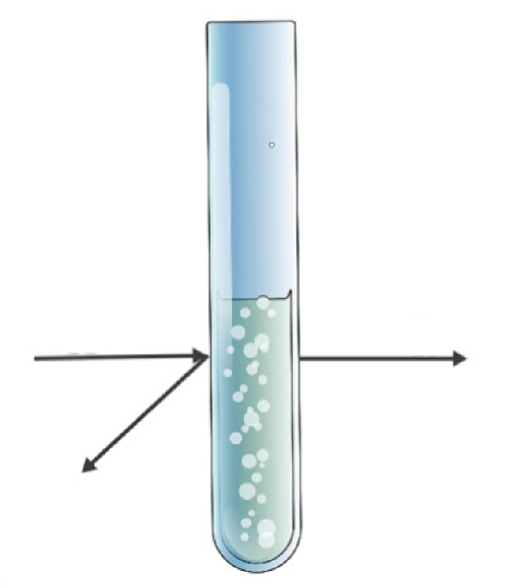

$\frac{dI}{dt}\;\textrm{=}\;\textrm{-}\;\textrm{μ}\textrm{I},\;\;\;I\left(2\right)=1$, $\mu =0\ldotp 35$

a) (10%) Write MATLAB code to approximate the light intensity at $t=4$ seconds for light passing through the fungus from $t=\left\lbrack 2\;\;\;\;\;5\right\rbrack$ seconds using `ode45`.

clear; clc; close all;

% Set up variables
tspan = [2 5];   % Time range
y0 = 1;          % Initial light intensity
mu = 0.35;       % Absorption coefficient

% Differential equation: dI/dt = -mu * I
f = @(t, y) -mu * y;

% Solve ODE numerically
[t, y] = ode45(f, tspan, y0);

% Evaluate solution at t = 4
fList = ode45(f, tspan, y0);
I_at_4 = deval(fList, 4);
fprintf('Light intensity at t = 4: %.4f\n', I_at_4);

Light intensity at t = 4: 0.4966


b) (10%) Find the analytical solution using [symbolic math](https://www.mathworks.com/help/symbolic/dsolve.html) or by hand and plot both the MATLAB's ODE solver and the analytical solution, with appropriate axes and legend. 

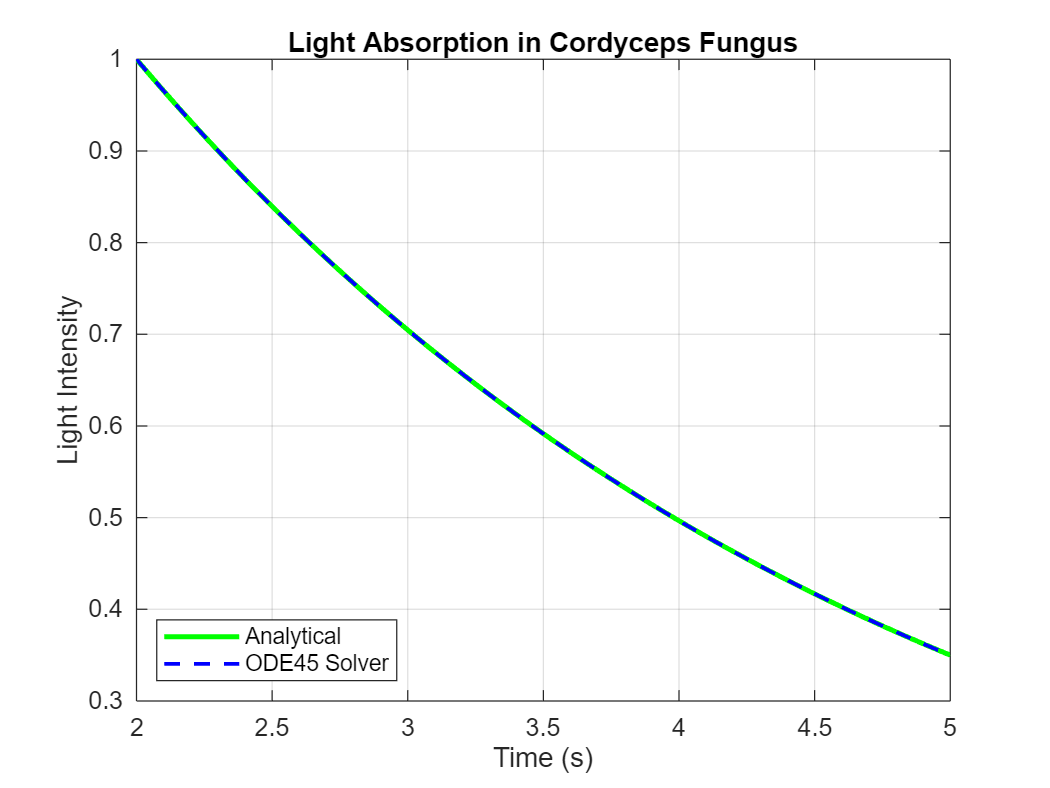

syms I(t_sym)

% Define the differential equation
eqn = diff(I, t_sym) == -mu * I;

% Initial condition
cond = I(2) == y0;

% Solve analytically
I_sol(t_sym) = dsolve(eqn, cond);

% Plot comparison
figure;

% Vector for plotting
tt = linspace(tspan(1), tspan(2), 100);

% Plot analytical solution
plot(tt, I_sol(tt), 'g', 'LineWidth', 2);
hold on;

% Plot numerical solution from ode45
plot(tt, deval(fList, tt), '--b', 'LineWidth', 1.5);
hold off;

legend('Analytical', 'ODE45 Solver', 'Location', 'southwest');
xlabel('Time (s)');
ylabel('Light Intensity');
title('Light Absorption in Cordyceps Fungus');
grid on;

Question 2 (20%)

In the infamous city of Raccoon City, population of 10,000, a catastrophic leak at the Umbrella Corporation laboratories unleashed the dreaded T-Virus. The viral contamination spread through the streets like wildfire, infecting the first five unfortunate citizens, who transformed into grotesque, mindless abominations with an insatiable hunger for human flesh. Panic and chaos erupted overnight, as the city teetered on the brink of total collapse.

Amid the chaos, a brave biomedical engineer infiltrated the quarantined zone, determined to understand the virus. Dodging grasping hands, collapsing buildings, and the relentless growls of the infected, they risked everything to measure the spread and decay parameters of the T-Virus. As the infected closed in, the engineer fell, clutching a bloodstained notebook. With their dying breath, they whispered a desperate plea:

*"You… must… solve… the model… before Raccoon City is lost…"*

From the engineer’s notes, you now know how the populations are expected to change: the human population decreases proportionally to both the number of humans and the infected, while the zombie population grows in proportion to human-to-zombie interactions but decays naturally over time without new hosts. Using the data they risked their life to gather, a bite-induced infection rate of  $0\ldotp 5x\;{10}^{-4}$ per hour and a zombie decay rate of $10\ldotp 3x\;{10}^{-2}$ per hour, you are tasked to predict the rise and fall of the T-Virus outbreak and determine whether any human soul might survive the creeping doom.

a) (5%) Write out the system of differential equations derived from the information above using the Equation Editor underneath the Insert tab. 


$$\begin{array}{l}
\frac{{\mathrm{dP}}_{\mathrm{Humans}} }{\mathrm{dt}}\textrm{=}-c_1 P_{\mathrm{Humans}} P_{\mathrm{Zombies}} \\
\frac{{\mathrm{dP}}_{\mathrm{Zombies}} }{\mathrm{dt}}=c_1 P_{\mathrm{Humans}} P_{\mathrm{Zombies}} -c_2 P_{\mathrm{Zombies}} 
\end{array}$$


b) (10%) Solve the coupled model for the zombie outbreak for the first 100 hours after the zombies appear. Plot the population of humans and zombies on a single graph with appropriate axes and legend.

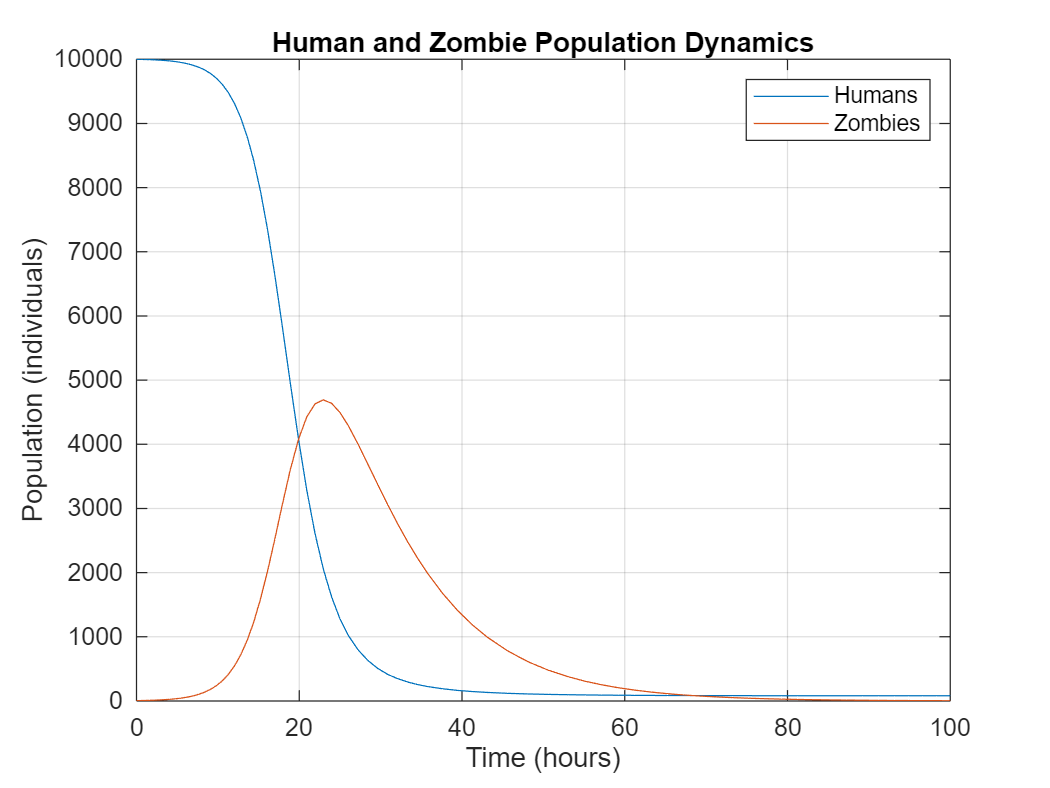

clear,clc,close all
% Set up time span for simulation
tspan = [0 100];           % Time interval from 0 to 100 hours
c1 = 0.5e-4; % Constant zombie creation rate
c2 = 10.3e-2;
% Initial populations: [humans, zombies]
y0 = [10000, 5];            % 10000 humans and 5 initial zombies

% Define the differential equations for the model
% y(1): human population, y(2): zombie population
% Human population decreases due to interaction with zombies
% Zombie population increases with human interactions and decreases due to starvation
predprey = @(t, s) [ ...
    -c1 * s(1) * s(2);    % Rate of decrease of humans due to zombies
     c1*s(1)*s(2) - c2 * s(2)  % Rate of change of zombie population
];

% Set up solver using ode45
[t, s] = ode45(predprey, tspan, y0);

% Plot the results
figure; 
plot(t, s); 
xlabel('Time (hours)');
ylabel('Population (individuals)');
legend('Humans', 'Zombies', 'Location', 'northeast');
title('Human and Zombie Population Dynamics');
grid on;  % Add grid for better readability

c) (5%) Using the model of the T-Virus outbreak in Raccoon City, determine whether there is a time point **after the initial surge of zombies** when the human population once again **surpasses the zombie population**. If such a time exists, report the earliest time when this occurs; otherwise, report the time when humans go extinct.

% s(:,1) = humans, s(:,2) = zombies
% t = time vector

% Set the time after which we start checking
t_start = 40;  % hours

% Find the first time after t_start when humans > zombies
for i = 1:length(t)
    if t(i) > t_start && s(i,1) > s(i,2)
        time_humans_win = t(i);
        break
    end
end

fprintf('Humans begin outnumbering zombies at %.2f hours.\n', time_humans_win);

Humans begin outnumbering zombies at 69.28 hours.


Question 3 (20%): 

a) (10%) Write the MATLAB code to compute the given second-order differential equation below, given that $\frac{\textrm{dy}\left(1\right)}{\textrm{dx}}=1$ and  $y\left(1\right)=1$ and x =[1 2].


$$x^2 \frac{d^2 y}{{dx}^2 }+3x\frac{dy}{dx}+y=0$$


clear,clc,close all
% Set up variables
tspan = [1 2]; 
y0 = [1; 1];
% Construct your state system
% s=[y y']
% s=[s(1) s(2)]
% s'=[s(1)' s(2)']
% s'=[y' y'']
% s'=[y' (-3xy'-y)/x^2]
% s'=[s(2) (-3*x*s(2)-s(1))/x^2 ]
% Set up function defining the system of ODEs
f = @(x, s) [s(2);...
            (-3*x*s(2) - s(1)) / x^2]; 

% Set up solver using ode45 to solve the system of ODEs
[x, s] = ode45(f, tspan, y0); 

b) (10%) Plot the solved system from (a) against the analytical answer, found using either [symbolic math](https://www.mathworks.com/help/symbolic/dsolve.html) or by hand, and provide appropriate axes and legend. 

% Define symbolic variable for analytical solution
syms ya(xa)                % Define symbolic function ya with variable xa

% Calculate the first derivative of ya
Dya = diff(ya, xa)         % First derivative of ya with respect to xa

$$Dya(xa) = \frac{\partial }{\partial \mathrm{xa}}\mathrm{ya}\left(\mathrm{xa}\right)$$

% Define the differential equation
eqn = diff(ya, xa, 2) == (-3*xa*Dya - ya) / xa^2 % Second-order ODE

$$eqn(xa) = \frac{\partial^{2}}{\partial {\mathrm{xa}}^{2}}\mathrm{ya}\left(\mathrm{xa}\right)=-\frac{3\,\mathrm{xa}\,\frac{\partial }{\partial \mathrm{xa}}\mathrm{ya}\left(\mathrm{xa}\right)+\mathrm{ya}\left(\mathrm{xa}\right)}{{\mathrm{xa}}^{2}}$$

% Define initial conditions
cond = [ya(1) == y0(1), Dya(1) == y0(2)] % Initial conditions for ya and its derivative

$$cond = \left(\begin{array}{cc} \mathrm{ya}\left(1\right)=1 & \left({\left(\frac{\partial }{\partial \mathrm{xa}}\mathrm{ya}\left(\mathrm{xa}\right)\right)|}_{\mathrm{xa}=1}\right)=1 \end{array}\right)$$

% Solve the ODE analytically
ySol(xa) = dsolve(eqn, cond) % Obtain the analytical solution

$$ySol(xa) = \frac{2\,\log\left(\mathrm{xa}\right)+1}{\mathrm{xa}}$$

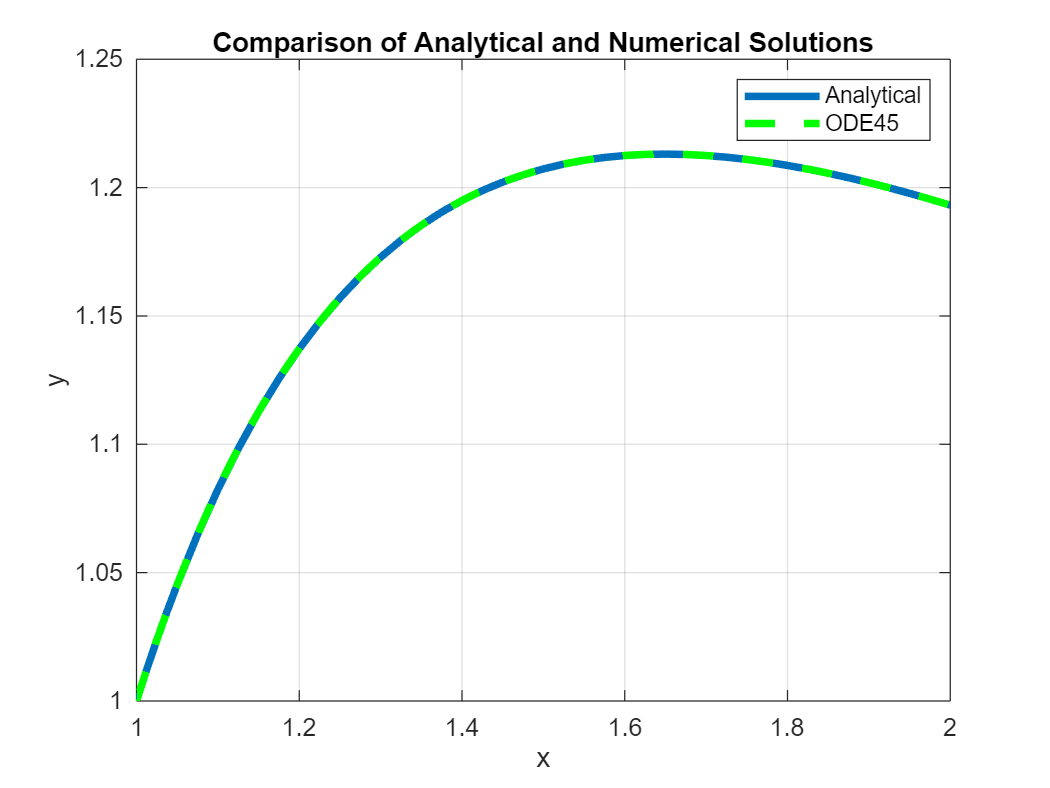

% Plotting the results
figure;                      % Create a new figure for the plot
xx = linspace(tspan(1),tspan(2));        % Define a range of x values for plotting the analytical solution

% Plot the numerical solution from ode45
plot(x, s(:, 1), '-','LineWidth',3); % Plot numerical y against time
hold on;                   % Hold the current plot for overlaying the analytical solution

% Plot the analytical solution
plot(xx, ySol(xx), 'g--','LineWidth',3); % Plot analytical solution in dashed green line

% Adding labels and title
xlabel('x');        % Label for the x-axis
ylabel('y');          % Label for the y-axis
title('Comparison of Analytical and Numerical Solutions'); % Title for the plot
legend ('Analytical','ODE45');               % Show legend for clarity
grid on;                  % Enable grid for better readability

Question  4 (20%): 

The following is an example of a potentially stiff ODE system:


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}\textrm{=}-x\\
\frac{\textrm{dy}}{\textrm{dt}}=x-\alpha \;y
\end{array}$$


a) (10%) If $\alpha \;$is 400000, find and plot the solution to the ODE system using [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) from t = 0 to 1. The initial value of x(0) and y(0) is 1.

clear; clc; close all;
% Set up variables/parameters
alpha = 400000;               % Parameter for the system
tspan = [0 1];                % Time interval for the simulation (0 to 1 second)
s0 = [1; 1];                  % Initial conditions: [s(1)(0), s(2)(0)] = [1, 1]

% Construct your state system
% s=[ x    y  ]
% s=[s(1) s(2)]
% s'=[s(1)' s(2)']
% s'=[-x  x-alpha*y]
% s'=[-s(1)  s(1)-alpha*s(2)]
f = @(t, s) [ ...             % Function defining the system
    -s(1);                     % ds(1)/dt = -s(1)
    s(1) - alpha * s(2)       % ds(2)/dt = s(1) - alpha * s(2)
];

% Set up solver and measure execution time using tic/toc
tic;                          % Start timer
[t, s] = ode45(f, tspan, s0); % Solve the ODEs using ode45
t_ode45 = toc               % Stop timer and store elapsed time

t_ode45 = 1.0086

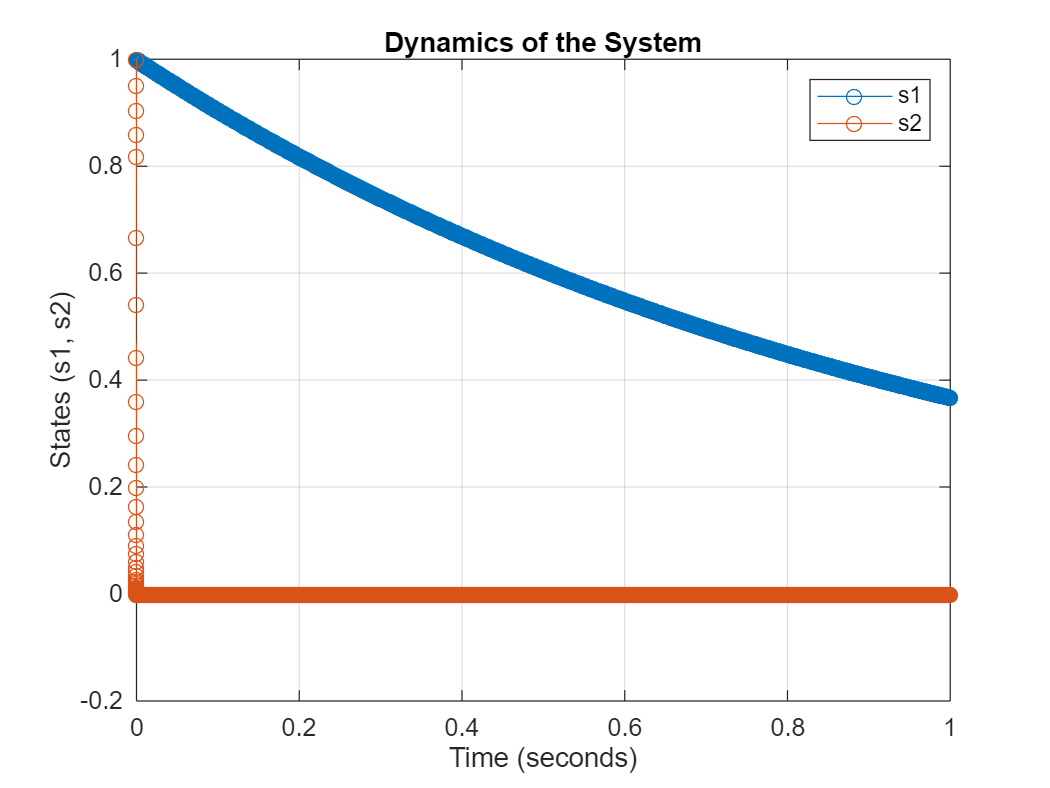


% Plot the results
figure;                     % Create a new figure
plot(t, s, '-o');          % Plot each variable against time with circle markers
xlabel('Time (seconds)');  % Label x-axis
ylabel('States (s1, s2)'); % Label y-axis
title('Dynamics of the System'); % Title for the plot
legend('s1', 's2');        % Legend to identify the variables
grid on;                   % Enable grid for better readability

b) (10%) Solve this ODE faster using a different, built-in, MATLAB ODE solver. Quantify how much better it is compared to ode45 from (a). Plot the solution and compare it to your results from (a). Why is this alternative solver, presumably, faster? 

Hint: Use [tic](https://www.mathworks.com/help/matlab/ref/tic.html) [toc](https://www.mathworks.com/help/matlab/ref/toc.html). Comparing solutions is easier if you include markers for data points.

% Set up solver for ode15s, which is generally faster for stiff systems.
% Note: The actual speed improvement will depend on the specific problem.
tic;                          % Start timer for performance measurement
[t, s] = ode15s(f, tspan, s0); % Solve the ODEs using ode15s
t_ode15s = toc              % Stop timer and record elapsed time

t_ode15s = 0.1287

% Display the speed comparison between ode45 and ode15s
fprintf('ode15s is %3.4fx faster than ode45.\n', t_ode45 / t_ode15s);

ode15s is 7.8377x faster than ode45.


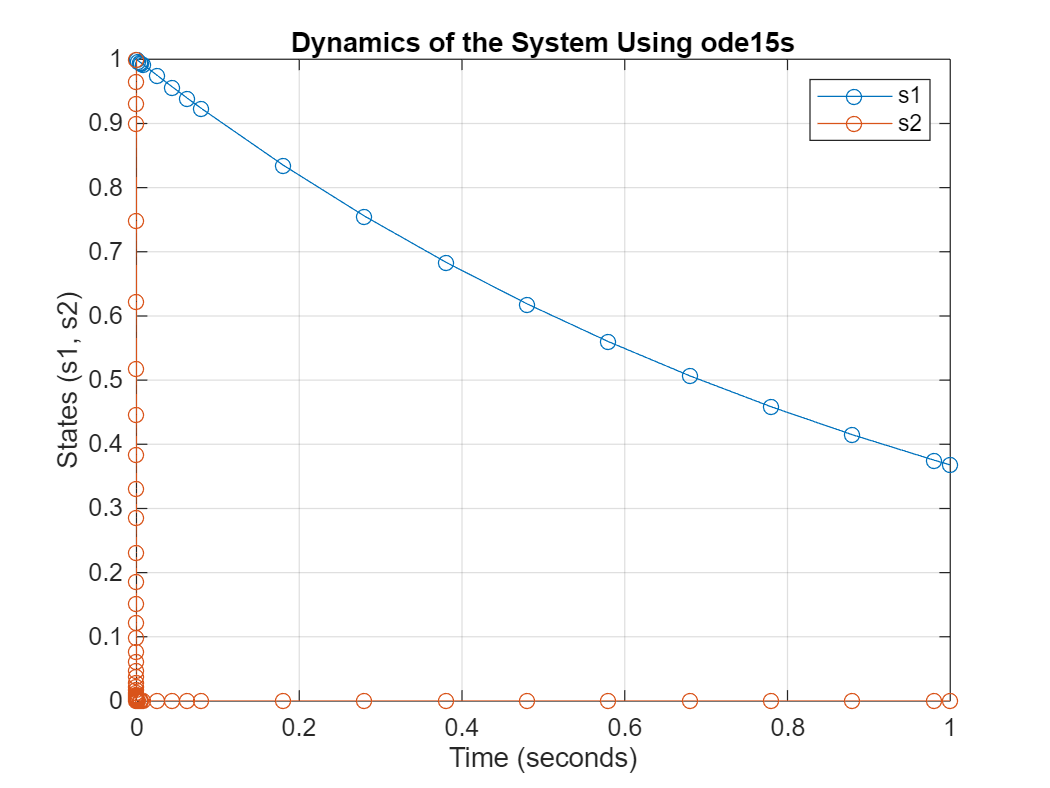

% Plot the results
figure;                     % Create a new figure
plot(t, s, '-o');          % Plot each state variable against time with circle markers
xlabel('Time (seconds)');  % Label x-axis
ylabel('States (s1, s2)'); % Label y-axis
title('Dynamics of the System Using ode15s'); % Title for the plot
legend('s1', 's2');        % Legend to identify the variables
grid on;                   % Enable grid for better readability

ode15s is a stiff solver meant for these kinds of systems. Rather than solving using the smallest time-step, like ode45, it adapts the time step depending on the behavior of the solution as it solves. Meaning, it uses a smaller time-step at sharp transitions and large ones where the function is behaving smoothly.

Question 5 (20%)

While exploring a dusty crypt, a team of archaeologists accidentally opened an ancient sarcophagus. To their shock, and mild horror, they found a still-beating heart inside! Most people would have run screaming, but one brave (or slightly reckless) biomedical engineer decided it was the perfect opportunity to model its dynamics instead of re-burying it.

The heart’s electrical activity can be approximated by a forced Van der Pol-like system:


$$\frac{\textrm{dV}}{\textrm{dt}}=W$$



$$\frac{\textrm{dW}}{\textrm{dt}}=\mu \left(1-v^2 \right)W-V+\gamma \sin \left(\omega \;t\right)$$



$$V\left(0\right)=1,W\left(0\right)=0$$


Where:

- $V\left(t\right)=$ voltage of the heart's beat,

- $W\left(t\right)=$ rate of change of voltage,

- $\mu =2$, nonlinearity parameter (how "possessed" the heart is),

- $\gamma =0\ldotp 5$, ghost forcing amplitude,

- $\omega =0\ldotp 4$, frequency of ghostly forcing

If parameter μ ≥ 0, the system will undergo stable oscillations, known as a [limit cycle](https://en.wikipedia.org/wiki/Limit_cycle) whereby the trajectory of the system will form a closed loop.

a) (10%) Solve and plot the Van der Pol ODE system result for a time-span of 100 s. Label axes appropriately and provide a legend.

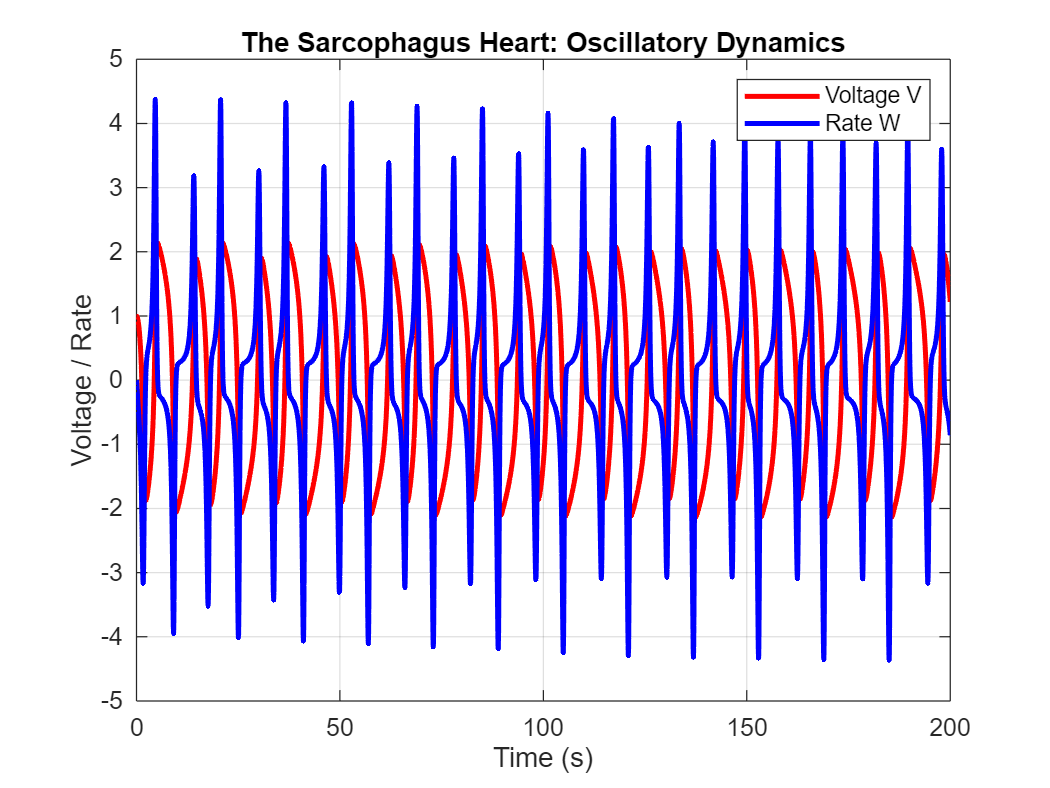

clear; clc; close all;

% Time span for simulation
tspan = [0 200];  

% Initial conditions [Voltage V(0), Rate W(0)]
y0 = [1; 0];  

% System parameters
mu = 2;         % Possession level of the heart
gamma = 0.5;    % Ghostly forcing amplitude
omega = 0.4;    % Frequency of ghostly forcing

% Set up the Van der Pol oscillator function
% Construct your state system
% s=[ V    W  ]
% s=[s(1) s(2)]
% s'=[s(1)' s(2)']
% s'=[V  μ*(1-V.^2)W - V + γsin(ωt)]
% s'=[s(2) μ*(1-s(1).^2)*s(2)-s(1) + + γsin(ωt)]
f = @(t, s) [ ...
    s(2);                      % V' = W
    mu*(1 - s(1)^2)*s(2) - s(1) + gamma*sin(omega*t)  % W' = nonlinear + ghostly forcing
];

% Solve the ODE numerically using ode45
[t, y] = ode45(f, tspan, y0);

% Plot voltage and rate
figure;
plot(t, y(:,1), 'r', 'LineWidth', 2); hold on;   % Voltage V(t)
plot(t, y(:,2), 'b', 'LineWidth', 2);           % Rate W(t)
xlabel('Time (s)');
ylabel('Voltage / Rate');
legend('Voltage V', 'Rate W');
title('The Sarcophagus Heart: Oscillatory Dynamics');
grid on;

b) (5%) Identify the peaks of $V\left(t\right)$ from part (a) to estimate the average heartbeat period and comment on its regularity.

% Identify peaks in V(t) to estimate heartbeat period
[peaks, locs] = findpeaks(y(:,1), t);  

% Compute average period between peaks
heartbeat_period = mean(diff(locs));

% Display result
fprintf('Estimated “heartbeat” period: %.2f seconds. Appears to be mildly possessed!\n', heartbeat_period);

Estimated “heartbeat” period: 8.05 seconds. Appears to be mildly possessed!


c) (5%) Investigate how increasing the ghostly forcing $\omega$ affects the frequency of $V\left(t\right)$ by plotting and comparing two values of $\omega \;$ 0.4 and 1.

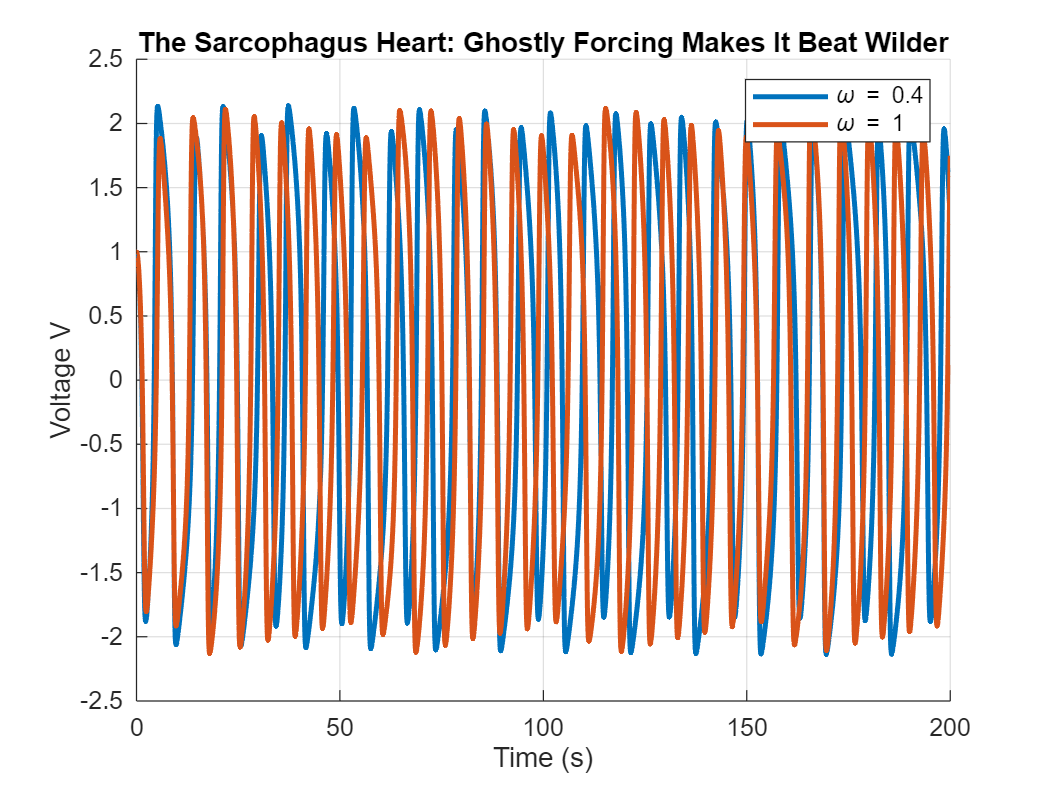

% Compare voltage with different ghostly forcing frequency
omega_values = [0.4, 1];  % Normal vs extra beating

figure; hold on;

for k = 1:length(omega_values)
    omega=omega_values(k);
    f = @(t, s) [ ...
        s(2);                      % V' = W
        mu*(1 - s(1)^2)*s(2) - s(1) + gamma*sin(omega*t)  % W'
        ];

    % Solve the ODE for each gamma value
    [t, y] = ode45(f, tspan, y0);
    plot(t, y(:,1), 'DisplayName', ['\omega = ' num2str(omega)], 'LineWidth', 2); % Plot voltage
end

xlabel('Time (s)');
ylabel('Voltage V');
legend('show');
title('The Sarcophagus Heart: Ghostly Forcing Makes It Beat Wilder');
grid on;